# Global Planner Simulation

## Function import

% RUN in file directory
addpath(genpath("../utils/"), genpath("../global_planner/"));

## Initialize

clear all; clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal
start = [3, 2];
goal = [18, 29];
% goal = [12, 16];

% planner
% graph search
% planner_name = "a_star";
% planner_name = "dijkstra";
% planner_name = "gbfs";
% planner_name = "jps";
% planner_name = "d_star";
planner_name = "voronoi_plan";

% sample search
% planner_name = "rrt";
% planner_name = "rrt_star";
% planner_name = "informed_rrt";
% planner_name = "rrt_connect";

% evolutionary search
% planner_name = "aco";

## Path planning

planner = str2func(planner_name);
[path, flag, cost, expand] = planner(grid_map, start, goal);

## Visualization

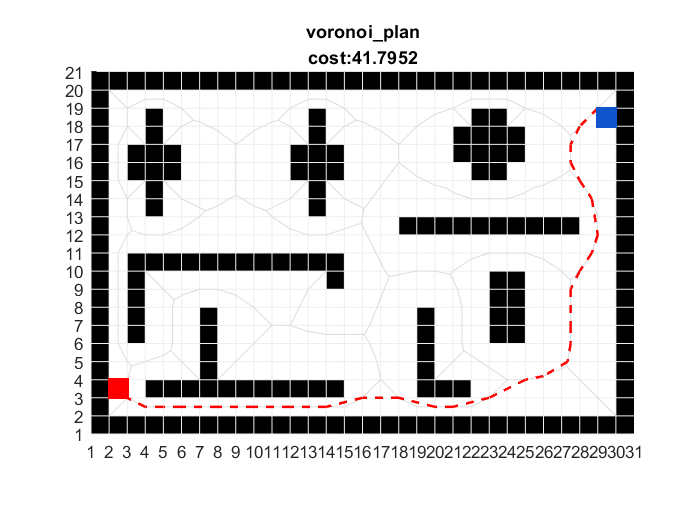

clf; hold on

% plot grid map
plot_grid(grid_map);

% plot expand zone
plot_expand(expand, map_size, G, planner_name);

% plot path
plot_path(path, G);

% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");
% title
title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');

hold off